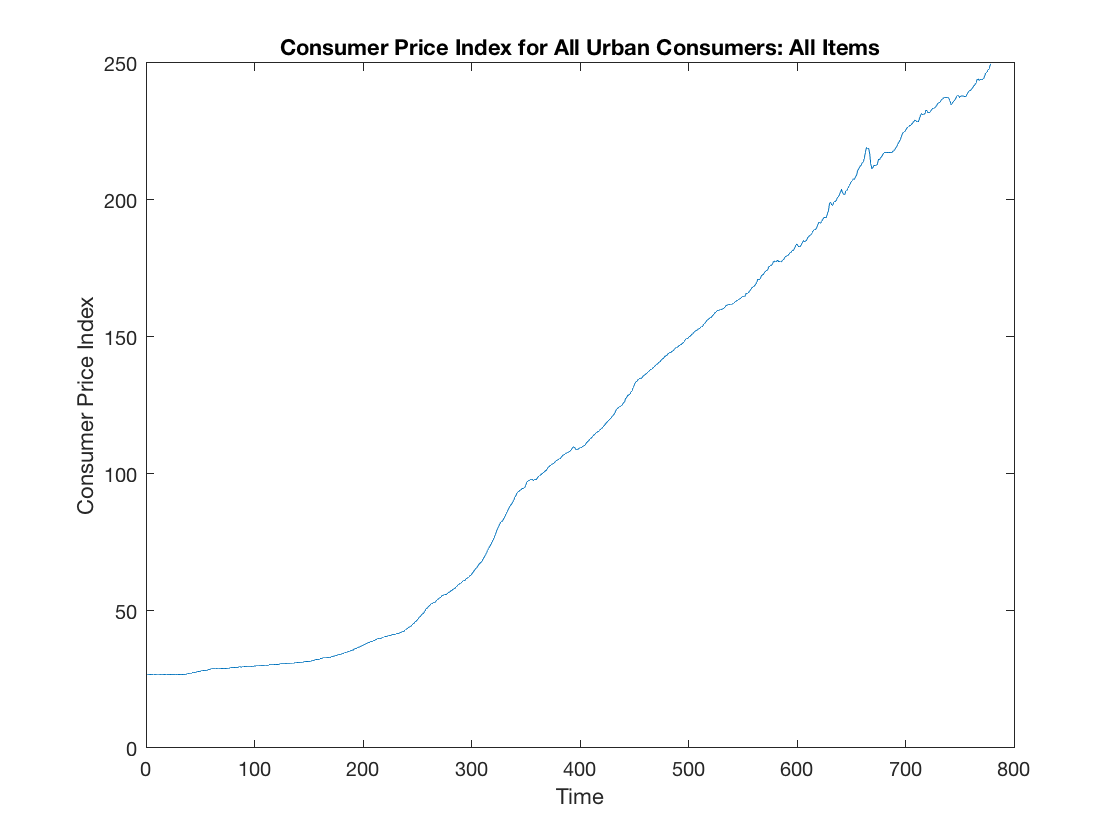

%% Loading data from source;
filename = "CPIAUCSL.csv";
data = csvread(filename, 1, 1);
data = data'; % Row time time series data.

%% Initialize figure;
figure
plot(data)
xlabel("Time")
ylabel("Consumer Price Index")
% Consumer Price Index for All Urban Consumers: All Items
title("Consumer Price Index for All Urban Consumers: All Items")


numTimeStepsTrain = floor(0.9 * numel(data));
XTrain = data(1: numTimeStepsTrain);

XTrain =    26.6900   26.7000   26.7700   26.7900   26.8500   26.8900   26.9500   26.8500   26.8700   26.9400   26.9900   26.9300   26.8600   26.9300   26.9400   26.8600   26.8500   26.8100   26.7200   26.7800   26.7700   26.7700   26.8200   26.7900   26.7900   26.7700   26.7100   26.7600   26.7200   26.8500   26.8200   26.8800   26.8700   26.8300   26.8600   26.8900   26.9300   27.0300   27.1500   27.2900   27.3100   27.3500   27.5100   27.5100   27.6300   27.6700   27.8000   27.8600   27.9300   28.0000


YTrain = data(2: numTimeStepsTrain + 1);
% One time step forward forcesting.
XTest = data(numTimeStepsTrain + 1: end -1);
YTest = data(numTimeStepsTrain + 2: end);

%% 